# Feature Engineering Techniques

The most important aspect of improving machine learning performance is finding the best features. Feature extraction is a very creative, iterative process that requires domain knowledge of the problem at hand. In this exercise we will try few ways of extracting useful information from our original dataset. 

The dataset can be found [here](https://archive.ics.uci.edu/ml/datasets/human+activity+recognition+using+smartphones):

`Dataset Courtesy:`` Davide Anguita, Alessandro Ghio, Luca Oneto, Xavier Parra and Jorge L. Reyes-Ortiz. A Public Domain Dataset for Human Activity Recognition Using Smartphones. 21th European Symposium on Artificial Neural Networks, Computational Intelligence and Machine Learning, ESANN 2013. Bruges, Belgium 24-26 April 2013. ` 

**What we will do in this exercise:**

clear variables
addpath(genpath(pwd));

## Extract statistical and spectral domain features

After exploring interactively a few different techniques to extract descriptive features from this type of signals, we've collected different analysis methods into a single function, [`extractSignalFeatures`](matlab:edit extractSignalFeatures.mlx). The responsibility of this function is to extract a fixed number of features for each signal buffer provided as input. 

**Features being extracted from each buffer for each acceleration component:**

- Average value in signal buffer 

- RMS value in signal buffer 

- Spectral peak features: height and position of first 6 peaks

- Autocorrelation features: height of main peak; height and position of second peak

- Spectral power features: total power in 5 adjacent and pre-defined frequency bands

**Note: Since we have more than 8000 buffers to process (training+validation+testing) the following section will take 5-7 minutes to complete if you extract the buffer live. **

clear;
extractFeaturesLive = false; % true: extract the features live

if extractFeaturesLive
    load('bufferedData.mat')
    trainFeatures = extractAllFeatures(trainData);
    validateFeatures = extractAllFeatures(validateData);
    testFeatures = extractAllFeatures(testData);
    
else
    load extractedFeatures.mat
end

% combine "test" set into "validation", like in module-02
validateFeatures = [validateFeatures;testFeatures];
validateN = numel(validateFeatures.activity);         % remember size for accuracy calculations later

**Train a model with new features **

Here we train the model programmatically using the KNN algorithm. Feel free to try different algorithms programmatically or use the App to train a variety of machine learning algorithms interactively. 

% Train the model with initial features 
mdl1 = fitcknn(trainFeatures,'activity');

% Validate the accuracy with our testing set 
newPred1 = mdl1.predict(validateFeatures);
accuracy1 = sum(validateFeatures.activity == newPred1) / numel(validateFeatures.activity) * 100

accuracy1 = 91.4474

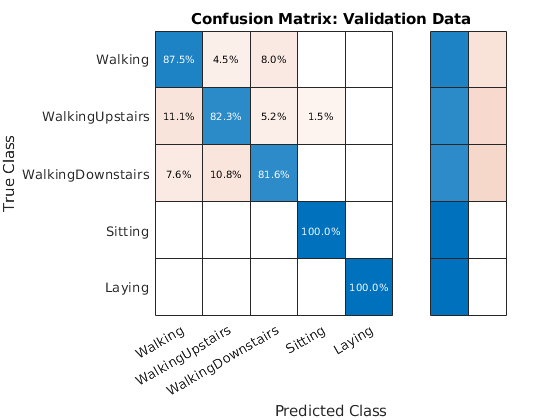

confusionchart(validateFeatures.activity, newPred1, 'RowSummary','row-normalized',...
    'Normalization','row-normalized','title','Confusion Matrix: Validation Data');    

## Select a subset of relevant features 

Now that we have more features to work with, we need to know which ones are useful as including unnecessary features can decrease accuracy. We will automate the process of feature selection using [Neighborhood Component Analysis (NCA)](matlab:web(fullfile(docroot, 'stats/fscnca.html'))). This produces a model that contains weights for each feature measuring its relative importance. 

We can see in the stem plot below that some features are much more important than others. This is very useful information as it can allow us to only work with the features that will most improve our accuracy.

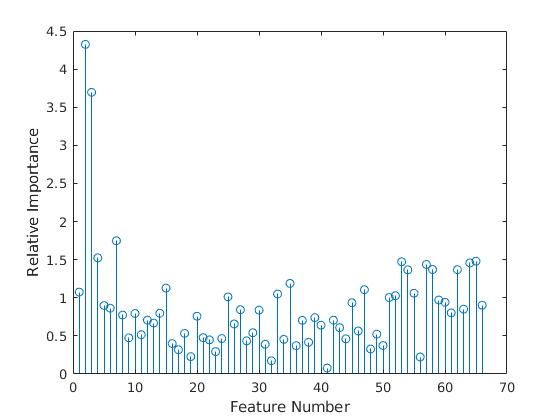

mdlNCA = fscnca(trainFeatures{:,vartype('double')},trainFeatures.activity);

figure
stem(mdlNCA.FeatureWeights)
xlabel('Feature Number');ylabel('Relative Importance');

**Extract useful features and validate the model **

Where to draw the boundary on what to include is a manual choice. You can change the threshold to see how the selected features affect the training accuracy.

**To do: **

- **Use the slider to change the threshold value for weights **

- **Observe the change in  accuracy of prediction with the testing dataset.**  

- **How many features did we reduce to from the original 66? **

% TO DO: modify threshold, and record relationship between #features and
% accuracy. Identify a threshold that preserves most of the accuracy.
threshold = 1;
idx = mdlNCA.FeatureWeights > threshold;
selectedFeatures = trainFeatures(:,[idx;true]);

% Train and validate the model 
mdl2 = fitcknn(selectedFeatures,'activity');
newPred2 = predict(mdl2,validateFeatures(:,[idx;true]));
accuracyValidate = sum(validateFeatures.activity == newPred2) / validateN * 100

accuracyValidate = 91.0526

%confusionchart(validateFeatures.activity, newPred2,'RowSummary','row-normalized',...
%    'Normalization','row-normalized','title','Confusion Matrix: Validation set');

**Test the final model with the test set  **

The testing data set is used only for testing the final solution in order to confirm the actual predictive power of the network.

*Note: since we merged the original test set to get a larger, more meaningful validation set, this result is not reliable. We'd need another held-out test set.*

newPred3 = predict(mdl2,testFeatures(:,[idx;true]));
accuracyTest = sum(testFeatures.activity == newPred3) / numel(testFeatures.activity) * 100

accuracyTest = 89.0547

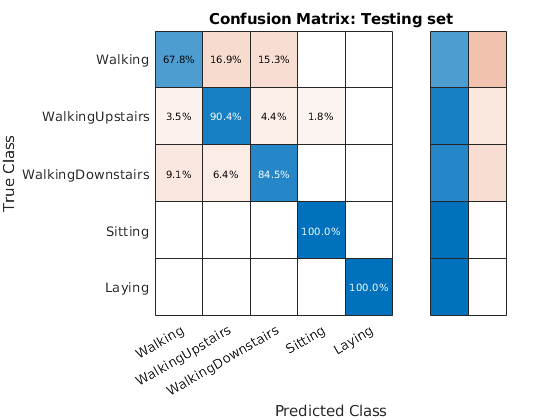

confusionchart(testFeatures.activity, newPred3,'RowSummary','row-normalized',...
    'Normalization','row-normalized','title','Confusion Matrix: Testing set');

## Automate Feature Extraction using Wavelet Scattering (*Optional*)

In the previous sections, we have seen how one can manually come up with a set of features by combining various approaches.  Another approach to automate the feature extraction process is by using a technique called Wavelet Scattering. Wavelet Scattering technique is a framework which is effective for automatically obtaining features that are compact and discrimative  while reducing the overall dimensionality of an input signal. 

**Load unbuffered data **

Wavelet scattering operates on the raw (unprocessed) data. We originally obtained that from the HAR dataset in module 02-Classification. For convenience, we'll just load the save .mat file here.

clear variables
load('unbufferedData.mat');

% display the counts of (signal) data points by subject and activity
unbufferedCounts = groupcounts(unbufferedTrain,{'subject','activity'})

unbufferedCounts = 125×3 table
    subject        activity         GroupCount
    _______    _________________    __________

       1       Walking                 6080   
       1       WalkingUpstairs         3392   
       1       WalkingDownstairs       3136   
       1       Sitting                 3008   
       1       Laying                  3200   
       2       Walking                 3776   
       2       WalkingUpstairs         3072   
       2       WalkingDownstairs       3008   
       2       Sitting                 2944   
       2       Laying                  3072   
       3       Walking                 3712   
       3       WalkingUpstairs         3776   
       3       WalkingDownstairs       3136   
       3       Sitting                 3328   
       3       Laying                  3968   
       4       Walking                 3840   


Notice the distribution of the data - we have 5 activities for each of the 25 subjects in the training set, but various amounts of data for each.

**Apply Wavelet scattering** 

At a minimum you need to provide **signal length** as input (which is the smallest number of samples in your data) and what you get as an output is a "blueprint" for wavelet  features for a given 1-D signal. For more information on the Wavelet scattering framework, [click here](matlab:web(fullfile(docroot, 'wavelet/gs/wavelet-time-scattering.html'))). 

We can create a wavelet scattering framework by specifying the size of the signal (at the minimum), the sample frequency (which was 50 Hz for this data), and what you get as an output is features for a given 1-D signal. 

N =  min(unbufferedCounts.GroupCount);    % Lowest number of samples for an activity X subject
sf = waveletScattering('SignalLength',N, 'SamplingFrequency',50);   % signal was sampled at 50 Hz! 

*Note (advanced, you may ignore for now): There is an optional parameter called "Invariance Scale" which is used to specify the length or segment of the signal (in seconds) for which the spectral features are assumed to be stationary (i.e. not changing). It needs to be expressed in seconds (of signal), and can vary between half to full signal length.There is no right or wrong value for this property and one can perform a parameteric sweep (invariance scale vs.  accuracy on validation data) to determine the optimum value. *

**Automatic Feature Extraction**

After constructing the scattering decomposition framework, obtain the scattering coefficients for the training data as a matrix.

For each activity for a particular subject, [featureMatrix(sf,x)](matlab:web(fullfile(docroot, 'wavelet/ref/waveletscattering.featurematrix.html'))) returns the scattering features for the scattering decomposition framework sf and the input signal x as a matrix of features across multiple subsections of the signal. Instead of a signal vector, we can also provide a matrix of observations from multiple signals, which in this case are the X, Y, and Z values of the accelerometer. Therefore featureMatrix returns a 3-dimensional matrix (the third dimension equalling the number of signals provided as input).

*For our data with the settings above, the scattering results in 156 features for 9 different sections of each observation (one sample of an activity performed by a specific subject). So the resulting feature table contains 156 x 3 = 468 features (columns) for each data point, plus the activity label, and there are 9 data points from each observation, therefore 9 x 5 activities x 25 subjects = 1125 rows in the feature table "trainFeatures".* *We can then train various machine learning models by using these features as input vector.*

**Important: ***If you use the Classification Learner, be careful to disregard the accuracy. It is **not** measured **on truly held-out data** (that's separate from the training data). The scattering represents each "observation" by several rows in the training data (9 in this case), and therefore a random selection of rows will distribute some rows into both the training and validation data.*

% Apply wavelet scattering to training set and train model 
trainFeatures = extractWaveletFeatures(unbufferedTrain,sf,N);

% We are deliberately NOT using the Classification Learner here (see note above)
mdl3 = fitcknn(trainFeatures,'activity');

**Test the model **

To get an idea of the accuracy with automatically extracted Wavelet features, we must do so on a test set that was manually separated from the training set. 

% Extract features from test data in the same way
unbufferedValCombo = [unbufferedValidate; unbufferedTest];
testFeatures = extractWaveletFeatures(unbufferedValCombo,sf,N);

Too many output arguments.


% Calcualte prediction accuracy
newPred3 = predict(mdl3,testFeatures);
accuracy3 = sum(testFeatures.activity == newPred3) / numel(testFeatures.activity) * 100
confusionchart(testFeatures.activity, newPred3, 'RowSummary','row-normalized','Normalization','row-normalized', 'Title', 'Confusion Chart: Testing Data');


**Conclusion: **We get about the same accuracy with test data than we did by extracting 66 features manually, and that with features that we obtained automatically from the signal!

## Design "Your Own" Features: DYI Feature Extraction (Optional)

Diagnostic Feature Explorer allows us to develop features and evaluate potential condition indicators using a multifunction graphical interface. The app operates on data ensembles. An ensemble is a collection of data sets, created by measuring or simulating a system under varying conditions. An individual dataset representing one system under one set of conditions is a member. 

With the Diagnostic Feature Designer, you can interactively: 

- Explore your data ensemble visually by plotting and interacting with your ensemble members together. 

- Convert your data into different forms for further exploration. For example, you can create a power spectrum of your signal to evaluate its frequency-domain behavior. Or you can perform time-synchronous averaging, which filters out any noise or disturbance that is not associated with your machine rotation. 

- Generate features of various types, and plot histograms that visualize their effectiveness in separating data from systems with different conditions. 

- Rank the features you have generated using ranking algorithms that use specific criteria to establish which features are most effective.

The diagnostic feature design currently needs the data in a particular format, each row containing data from one signal only. We have prepared the training set for you this way in the "dataForApp" file, but only 10 of the 25 subjects (to limit execution time of the feature processing inside the App).

**To do: **

- **Load the data **load("03-HelperFiles\dataForApp.mat")

- **Open the Diagnostic Feature Designer**

- **Import **sensorDataApp** as "multiple" ensemble. **Be sure to declare Time as "Independent Variable" 

- **Generate several time domain features. Identify which ones help separate the classes. Do this for X, Y, and Z.**

- Compute the spectrum and do the same with spectral features. 

- Perform feature ranking

- Train some models: Export the "best" features to the Classification Learner, and revisit the models that did well with the buffered means and standard deviations above. Accuracy will be slightly below the best models above, but we are training on just 1/5 of the data.

For more information, [click here](https://www.mathworks.com/help/releases/R2019a/predmaint/ref/diagnosticfeaturedesigner-app.html).

## Conclusion

There are numerous ways in which you can dissect your data and extract the features. The techniques used will depend on the application and the kind of data you are working with. 

**If you get done with the above sections, feel free to browse through different documentation examples to see a variety of feature extraction techniques along with different flavors of machine learning examples. **

- [Radar Target Classification](https://www.mathworks.com/help/releases/R2018b/phased/examples/radar-target-classification-using-machine-learning.html) (phased array and wavelets)

- [ECG Signal Classification ](https://www.mathworks.com/help/releases/R2018b/wavelet/examples/ecg-signal-classification-using-wavelet-time-scattering.html)(signal data and wavelet time scattering)

- [Speaker Identification using Pitch and MFCC](https://www.mathworks.com/help/releases/R2018b/audio/examples/speaker-identification-using-pitch-and-mfcc.html) (audio data)

- [Rolling Element Bearing Fault Diagnosis](https://www.mathworks.com/help/releases/R2018b/signal/examples/rolling-element-bearing-fault-diagnosis.html) (signal data and spectral analysis)

- [Machine Fault Detection](https://www.mathworks.com/help/releases/R2018b/predmaint/ug/Fault-Detection-Using-Data-Based-Models.html) (vibration data)

- [Classifying Protein Profiles](https://www.mathworks.com/help/releases/R2018b/bioinfo/examples/identifying-significant-features-and-classifying-protein-profiles.html) (mass spectrometry data)

- [Image Category Classification](https://www.mathworks.com/help/releases/R2018b/vision/examples/image-category-classification-using-bag-of-features.html) (image data)

- [Sentiment Classifier ](https://www.mathworks.com/help/releases/R2018b/textanalytics/ug/train-a-sentiment-classifier.html)(text data)

- [Automated Credit Rating Tool](https://www.mathworks.com/help/stats/examples/credit-rating-by-bagging-decision-trees.html) (finance)

- [Forecasting Corporate Default Rates](https://www.mathworks.com/help/releases/R2018b/finance/examples/forecasting-corporate-default-rates-1.html) (finance)

- [Airline Delay Prediction](https://www.mathworks.com/help/stats/examples/statistics-and-machine-learning-with-big-data-using-tall-arrays.html) (Big Data)

- [Gas Mileage Prediction ](https://www.mathworks.com/help/releases/R2018b/fuzzy/gas-mileage-prediction.html)(adaptive neuro-fuzzy modeling)

- [Deep Learning Examples ](https://www.mathworks.com/help/releases/R2018b/deeplearning/deep-learning-applications.html)